# Taratura manuale dell'anello di velocità

Determinare $C(s)$ in modo che soddisfi una frequenza di taglio desirata

In quest'esempio il controllore è un PI


$$C(s)=PI(s)=\frac{K_p\cdot s+K_i}{s}=K_p\left(1+\frac{1}{T_i s}\right)=K_p \frac{T_i s +1}{T_i s}$$


il processo è la funzione di trasferimento, in questo caso coppia - velocità lato motore

clear all;close all;clc;
load ('../script_lab_auto/' + "model_joint2.mat");
%load ../model_joint1.mat;
Ts=1e-3;
s=tf('s');
sys_vel_motore=tf(modello_continuo);
w0 = 2*pi*0.1;
w1 = 2*pi*300; %frequenze usate nel chirp

Con funzione di trasferimento

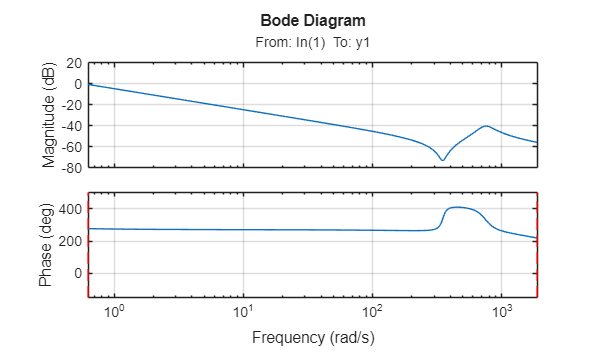

figure
bode(sys_vel_motore)
xlim([w0 w1])
ylim([-150 500])
grid on
hold on
plot(w0*[1 1],ylim,'--r')
plot(w1*[1 1],ylim,'--r')
hold off

Vorrei un $\omega_c$ prossima all'antirisonanza (che è attorno a 200 rad/s)

wc=60;

L'azione integrale mi sfasa, la metto almeno una decade prima.

wi=wc/20; % pulsazione azione integrale, wc/20 più robusto altrimenti wc/10
Ti=1/wi;

Il mio controllore sarà


$$C(s)=K_p \left(1+1/(Ti\cdot s)\right)=K_p C_o(s)$$


con $C_o(s)=$

s=tf('s');
Co=1+1/(Ti*s);

Calcolo $K_p$ in modo che $C(s)*P(s)=K_p \left(C_o(s)*P(s)\right)$ abbia modulo 1 in $\omega_c$. 

$|K_p \left(C_o(j\omega_c)*P(j\omega_c)\right)|=1 $ quindi $K_p=1/| \left(C_o(j\omega_c)*P(j\omega_c)\right)|$

Kp=1/abs(freqresp(Co*sys_vel_motore,wc));
C=Kp*Co


C =
 
  34.89 s + 104.7
  ---------------
     0.3333 s
 
Continuous-time transfer function.


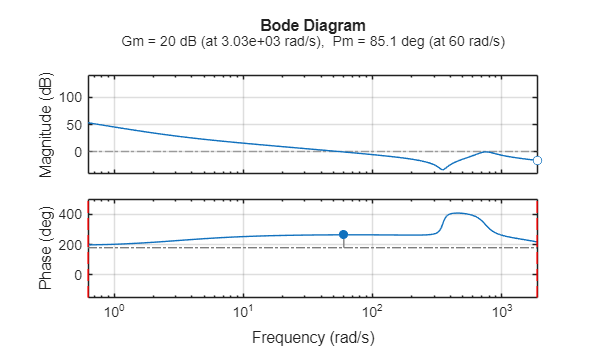

figure
margin(C*sys_vel_motore)
xlim([w0 w1])
ylim([-150 500])
grid on
hold on
plot(w0*[1 1],ylim,'--r')
plot(w1*[1 1],ylim,'--r')
hold off

Il diagramma di bode taglia più volte, meglio aggiungere un filtro per abbassare il picco.

Kp_code = Kp

Kp_code = 104.6793

Ki_code = Kp/Ti

Ki_code = 314.0378

#### Filtro Notch

Un filtro notch è un'elimina banda. La zona da eliminare è 

damp(sys_vel_motore)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -7.33e-02                 1.00e+00       7.33e-02         1.36e+01    
 -1.08e+02 + 7.42e+02i     1.44e-01       7.50e+02         9.27e-03    
 -1.08e+02 - 7.42e+02i     1.44e-01       7.50e+02         9.27e-03    
 -7.04e+03                 1.00e+00       7.04e+03         1.42e-04    


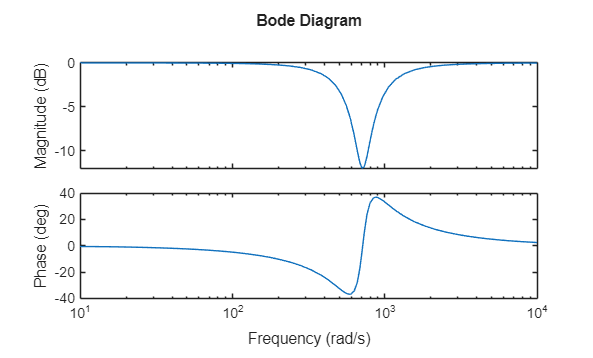

wn=715; % pulsazione risonanza quindi della coppia ocmplessa
%aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.4;
xci_z=0.1; 
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
figure
bode(notch)

Per il PI, il "nuovo" sistema da controllare è

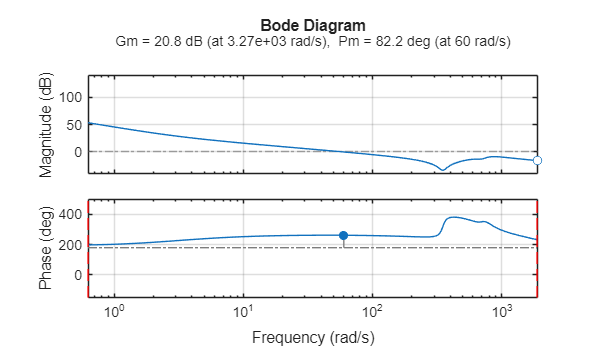

P=sys_vel_motore*notch;
Kp=1/abs(freqresp(Co*P,wc));
C=Kp*Co;
figure
margin(C*P)
xlim([w0 w1])
ylim([-150 500])
grid on
hold on
plot(w0*[1 1],ylim,'--r')
plot(w1*[1 1],ylim,'--r')
hold off

Potrei voler aggiungere altri poli (ad esempio un passa basso)